ノッチフィルタのステップ応答はオーバーシュートすることがある、の確認。

連続時間系にて、ノッチフィルタの伝達関数


$$ G(s)=\frac{s^2+d\cdot2\zeta\omega_ns+\omega_n^2}{s^2+2\zeta\omega_ns+\omega_n^2}$$


clear;
s = tf('s');

omega_n = 100*2*pi; %100[Hz]

オーバーシュートしないノッチフィルタ

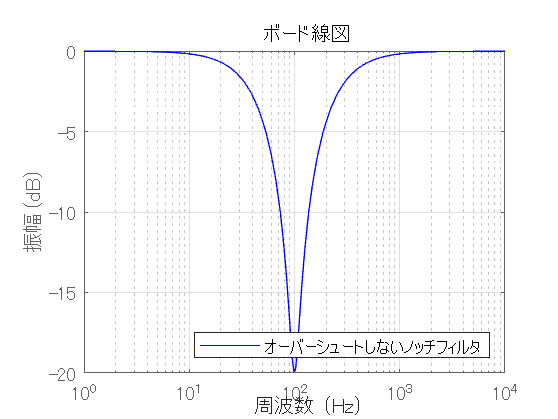

d1 = 0.1; % 深さパラメータ
zeta1 = 1; % 幅パラメータ

Notch1 = tf([1 d1*2*zeta1*omega_n, omega_n^2],[1 2*zeta1*omega_n, omega_n^2]);
text1 = append('(', poly2str(Notch1.Numerator{1},'s'), ')/(',  poly2str(Notch1.Denominator{1},'s'),')');
bodemag(Notch1,'b'); legend('オーバーシュートしないノッチフィルタ','Location','southeast');  grid on;

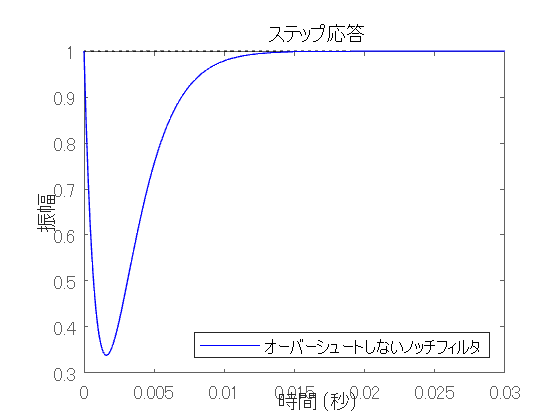

% h = findobj(gcf,'type','line'); 
% set(h,'linewidth',4); %プロットの線を太くする
step(Notch1,'b',0.03); legend('オーバーシュートしないノッチフィルタ','Location','southeast');

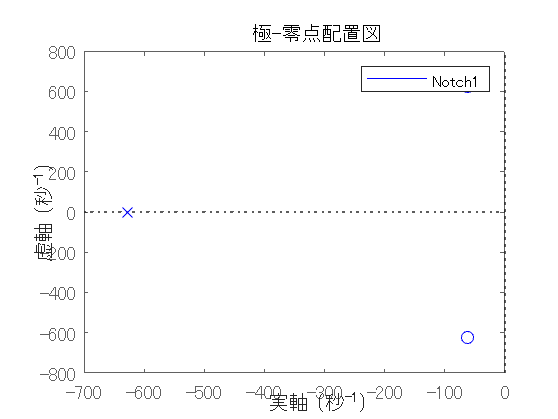

% h = findobj(gcf,'type','line'); 
% set(h,'linewidth',4); %プロットの線を太くする
pzmap(Notch1,'b'); legend;

オーバーシュートするノッチフィルタ

→幅パラメータζが小さい。

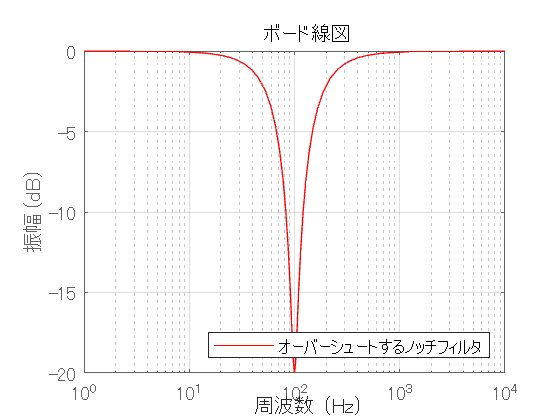

d2 = 0.1; % 深さパラメータ
zeta2 = 0.6; % 幅パラメータ

Notch2 = tf([1 d2*2*zeta2*omega_n, omega_n^2],[1 2*zeta2*omega_n, omega_n^2]);
bodemag(Notch2,'r'); legend('オーバーシュートするノッチフィルタ','Location','southeast'); grid on;

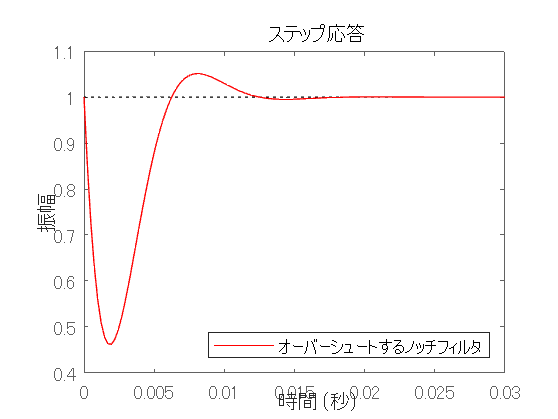

% h = findobj(gcf,'type','line'); 
% set(h,'linewidth',4); %プロットの線を太くする
step(Notch2,'r',0.03); legend('オーバーシュートするノッチフィルタ','Location','southeast');

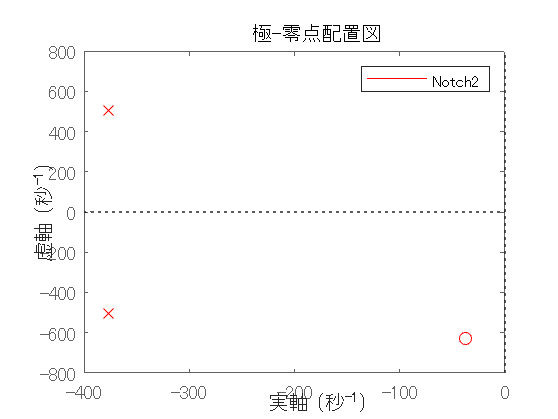

% h = findobj(gcf,'type','line'); 
% set(h,'linewidth',4); %プロットの線を太くする
pzmap(Notch2,'r'); legend;

2つのノッチフィルタ比較

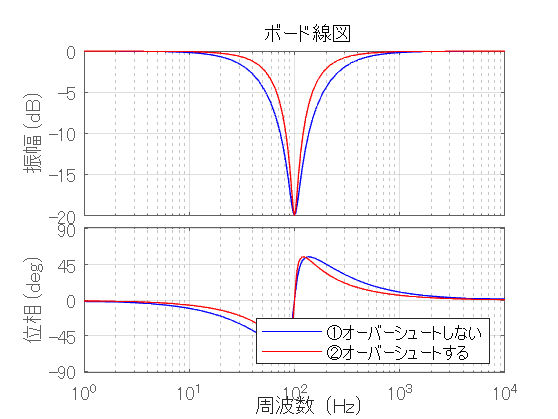

bode(Notch1,'b',Notch2,'r'); legend({'①オーバーシュートしない','②オーバーシュートする'},'Location','southeast'); grid on;

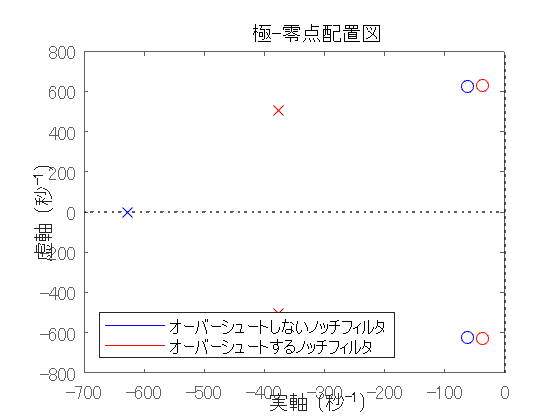

% h = findobj(gcf,'type','line'); %プロットの線を太くする
% set(h,'linewidth',4);
pzmap(Notch1,'b',Notch2,'r'); legend({'オーバーシュートしないノッチフィルタ','オーバーシュートするノッチフィルタ'},'Location','southwest');

オーバーシュートするノッチフィルタは分母分子で分解すると、

分母にボード線図上は隠れてしまう極がいることがわかる

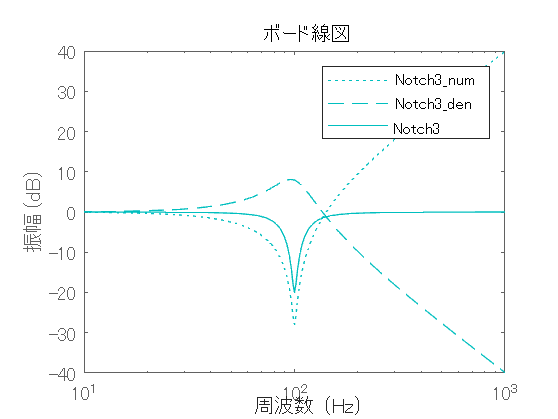

d3 = 0.1; % 深さパラメータ
zeta3 = 0.2; % 幅パラメータ % ↑だと分かりにくいのでもっと極端な例

plotoptions = bodeoptions;
plotoptions.MagUnits = 'abs';
Notch3 = tf([1 d3*2*zeta3*omega_n, omega_n^2],[1 2*zeta3*omega_n, omega_n^2]);
Notch3_num = tf([1 d3*2*zeta3*omega_n, omega_n^2],[omega_n^2]);
Notch3_den = tf([omega_n^2],[1 2*zeta3*omega_n, omega_n^2]);
bodemag(Notch3_num,'c:',Notch3_den,'c--',Notch3,'c'); legend;

ノッチの深さを変えたパターン。これもオーバーシュートしない

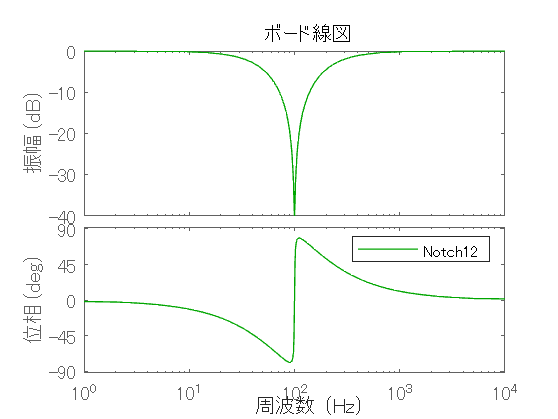

Notch12 = tf([1 0.01*2*zeta1*omega_n, omega_n^2],[1 2*zeta1*omega_n, omega_n^2]);
bode(Notch12,'g'); legend;

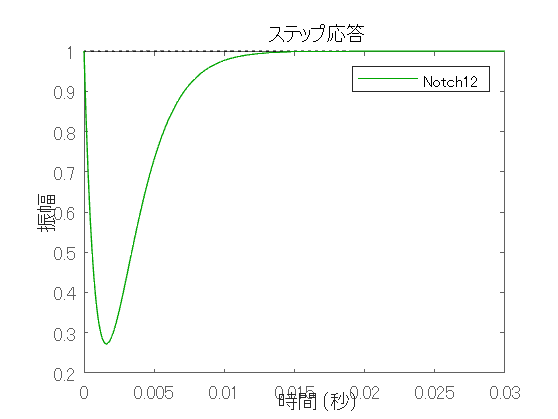

step(Notch12,'g',0.03); legend;

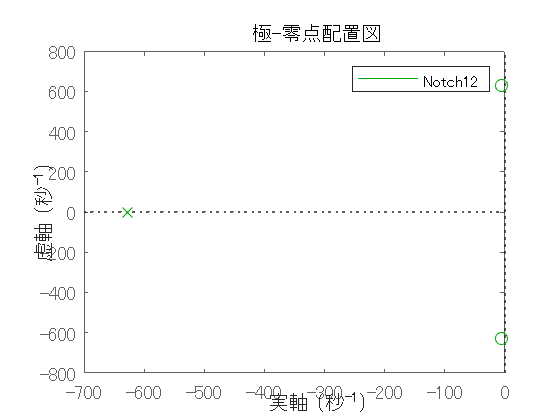

pzmap(Notch12,'g'); legend;

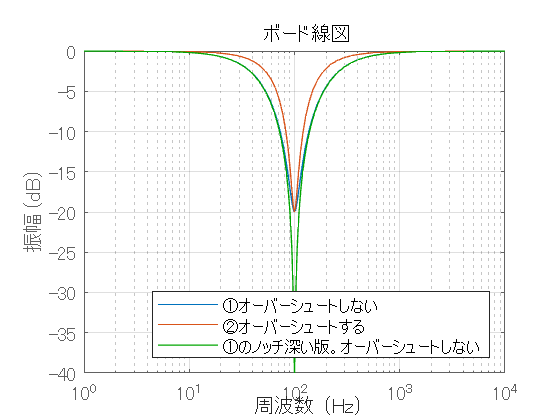


bodemag(Notch1,Notch2,Notch12,'g'); legend({'①オーバーシュートしない','②オーバーシュートする','①のノッチ深い版。オーバーシュートしない'},'Location','southeast'); grid on;

% h = findobj(gcf,'type','line'); %プロットの線を太くする
% set(h,'linewidth',2);

虚軸上に極があってもオーバーシュートしない、の例

古典制御理論基礎編(荒木光彦)、4.2.4のp.106、(ⅴ)の伝達関数より。

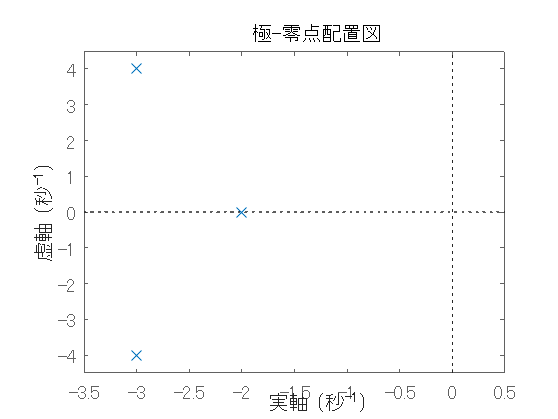

G5_ptn1 = CalcG5(3,4,2);
pzmap(G5_ptn1)
% h = findobj(gcf,'type','line'); %プロットの線を太くする
% set(h,'linewidth',2);
xlim([-3.5 0.5])
ylim([-4.5 4.5])

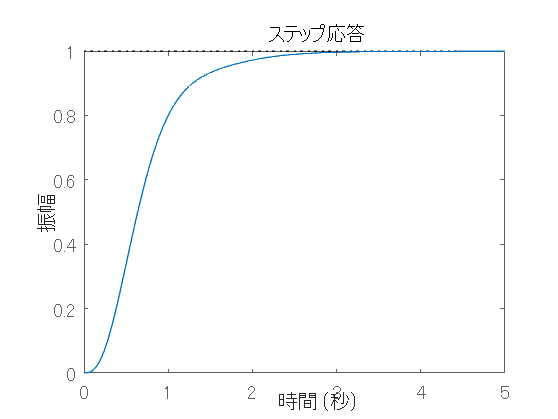

step(G5_ptn1,5)

% h = findobj(gcf,'type','line'); %プロットの線を太くする
% set(h,'linewidth',2);